**Problem 1**


$$L(s) = \frac{100(0.5s+1)}{s(0.2s+1) (s+10)}$$


Part a

It's difficult for me to do the sketches in Matlab, but I can certainly graph all of the components and then the correct answer.

Here are the Bode plots for each individual component.

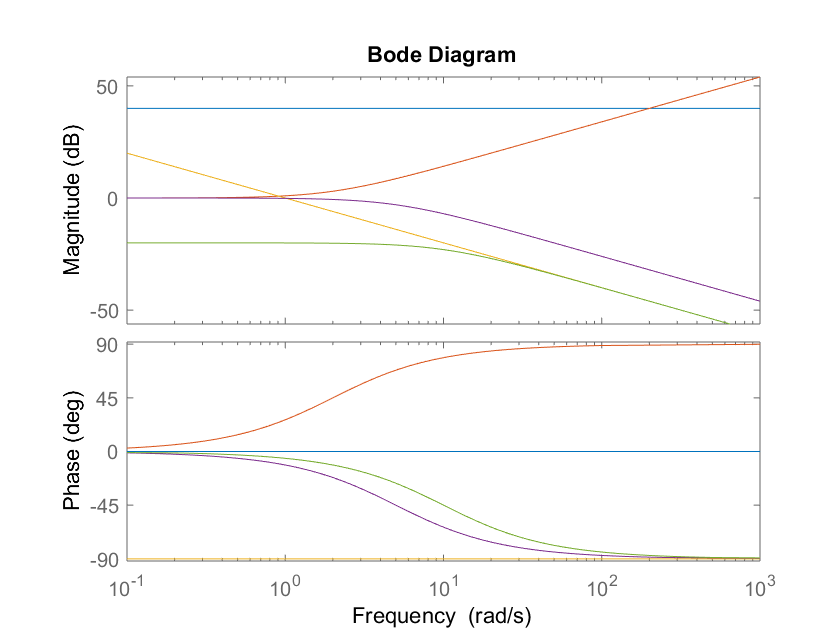

s = tf('s');
bode(tf(100,1),0.5*s+1,1/s,1/(0.2*s+1),1/(s+10))

When you add up all the plots you should get something that looks like this

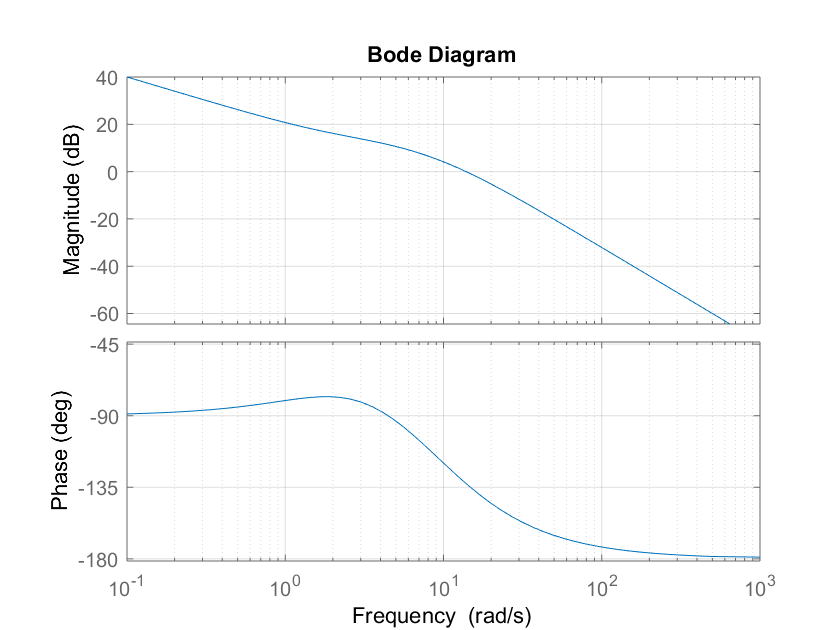

L = 100*(0.5*s+1)/s/(0.2*s+1)/(s+10);
bode(L)
grid

Now I need to sketch the Nyquist plot.  I unfortunately has a pole at the origin, and so I know there will be an infinite arc from 0 degrees to -90 degrees before the Bode plot kicks in.

NOTE:  The regular nyquist command in Matlab does not handle those infinite circles.  The attached command nyquist1, however, does.

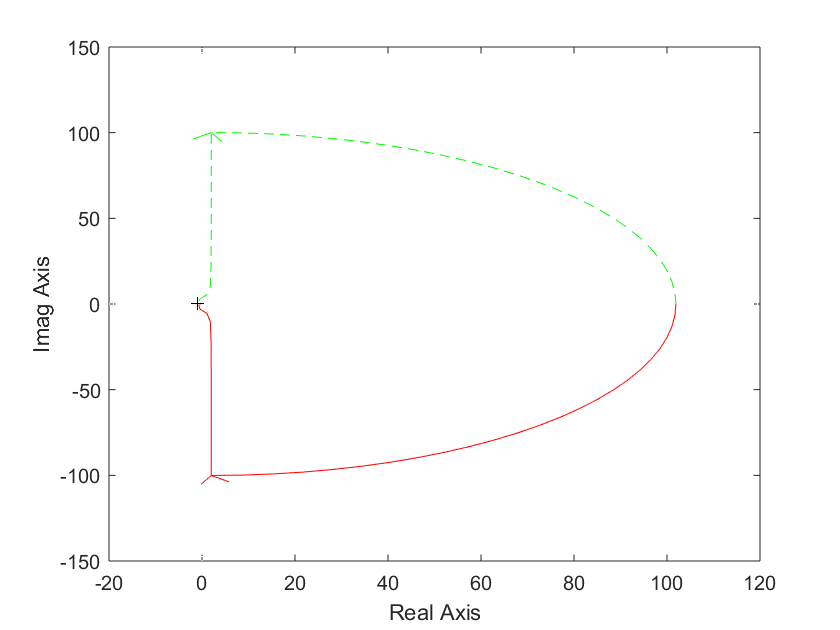

nyquist1(L)

Part b

Again, this is a little tough for me to sketch in the live editor, but I can certainly use the margin command.  By inspection, the phase never crosses 180 degrees, so the gain margin is infinite (stable for all values of K).  By eyeballing the Bode plot above, the zero dB crossover is about 15 rad/s, which corresponds to a phase of about -135 degrees.  So I would say the phase margin is around 45 degrees.

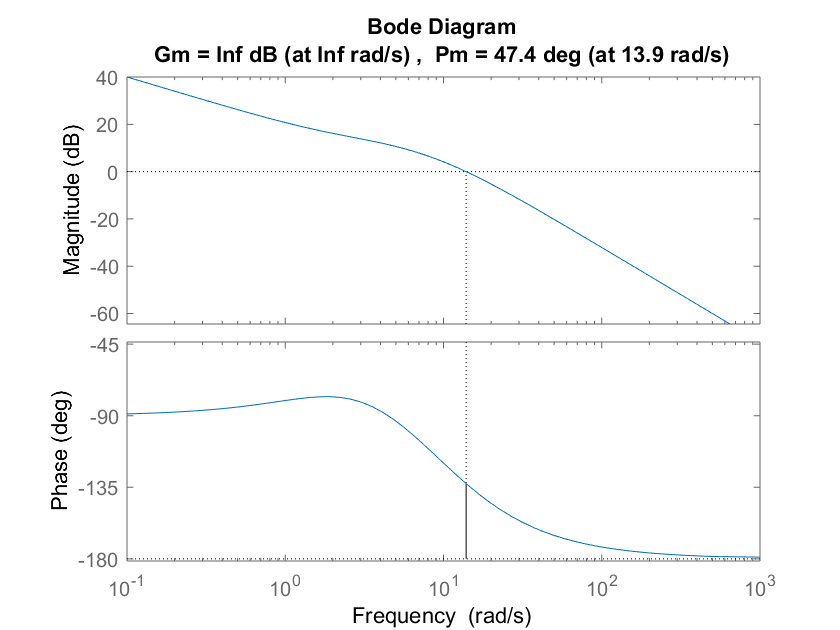

margin(L)

Part c

The delay margin is directly related to the phase margin via $DM = \frac{PM}{\omega}$

PM = 47.4*pi/180;  %Need this in radians
omega = 13.9;  %This is the crossover frequency
DM = PM/omega

DM = 0.0595

On an unrelated note, this section asks me to generate the step response of the closed loop system.

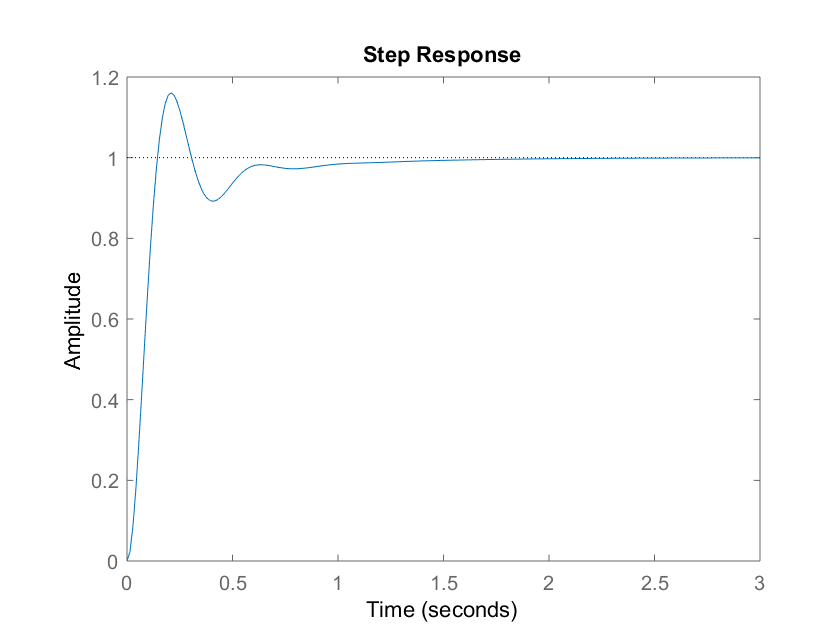

T = feedback(L,1);
step(T)

**Problem 2**


$$G(s) = \frac{100}{s(s+1)(s+10)$$


Part a

Lead compensator design is not too back.  We need to find the phase of the plant at the crossover frequency to determine how much phase lead is needed.

G = 100/s/(s+1)/(s+10);
[mag,phase] = bode(G,5)  %Just want the values at the desired crossover

mag = 0.3508

phase = -195.2551

Now I need to add the phase necessary to get to a phase margin of 60 degrees.  This whole process can be easily automated for normal looking systems.

PM = 60;
lead_angle = (-180-phase)+PM

lead_angle = 75.2551

Given an angle and frequency, the lead design is trivially computed.  I'll use a script to to this (attached to solutions).

Clead = lead(lead_angle,5);

To complete the design, I need to find the gain necessary to force 5 rad/s to be the crossover frequency.

[mag,phase] = bode(G*Clead,5);
K = 1/mag;

Now let's look at the answer.  

C = K*Clead


C =
 
  22.03 s + 14.25
  ---------------
     s + 38.64
 
Continuous-time transfer function.



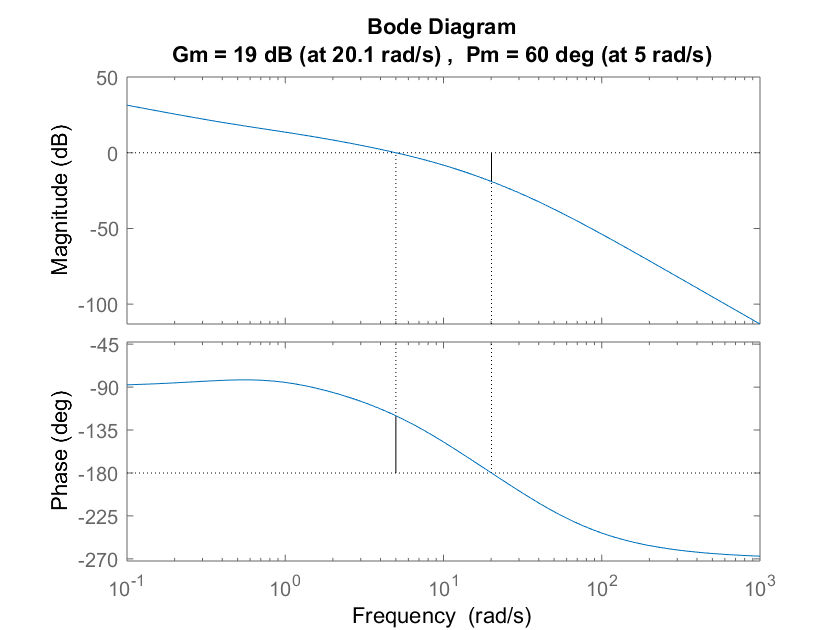

margin(G*C)

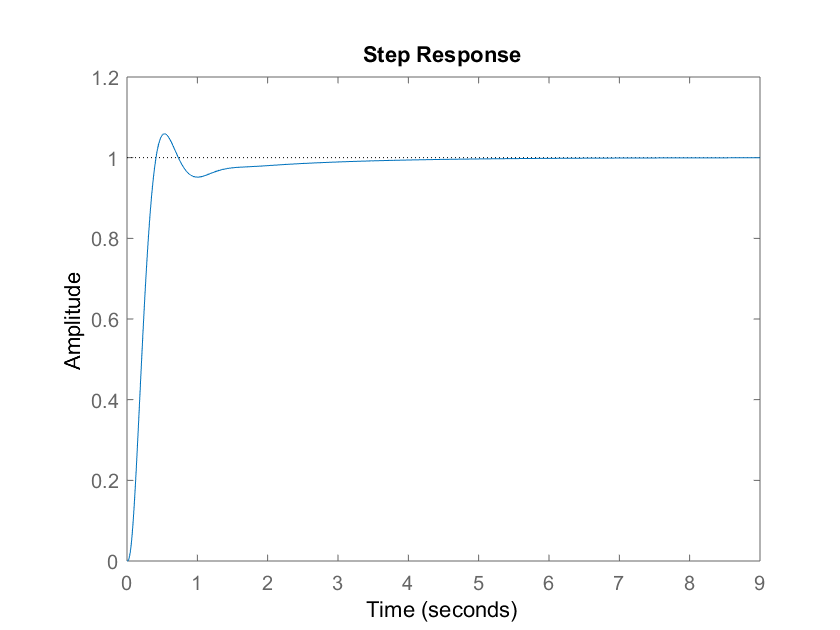

T = feedback(G*C,1);
step(T)

Part b

This is probably the most time consuming problem.  Jumping to state space is not bad.

Gss = ss(G)


Gss =
 
  A = 
         x1    x2    x3
   x1   -11  -2.5     0
   x2     4     0     0
   x3     0  0.25     0
 
  B = 
       u1
   x1   8
   x2   0
   x3   0
 
  C = 
         x1    x2    x3
   y1     0     0  12.5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Now I need to find the desired pole locations from the specifications - thankfully there are formulas for those.

zeta = -log(.20)/sqrt(pi^2+(log(.20)^2))

zeta = 0.4559

w = 4/zeta/6

w = 1.4621

Given these values, I know that I want the denominator to look like $s^2+2\zeta\omega_ns+\omega_n^2$, with poles at 

polesd = roots([1 2*zeta*w w^2])

polesd =   -0.6667 + 1.3013i
  -0.6667 - 1.3013i


Here's my thought process from here.  I'll place two of the poles at these desired locations, throw the other one 10x farther away, and then throw all three of the observer poles 10x farther away than that.  I'll just use the standard commands from Matlab to do the design.

[A,B,C,D] = ssdata(Gss);
K = place(A,B,[polesd;-7])

K =    -0.3333    0.0460    1.8706


Now the observer

L = place(A',C',[-70;-80;-90])'  %These can't be the same or Acker chokes

L = 	1.0e+04 *

    2.5554
    0.5303
    0.0018


Now I can throw the system together using the *reg* command in Matlab.

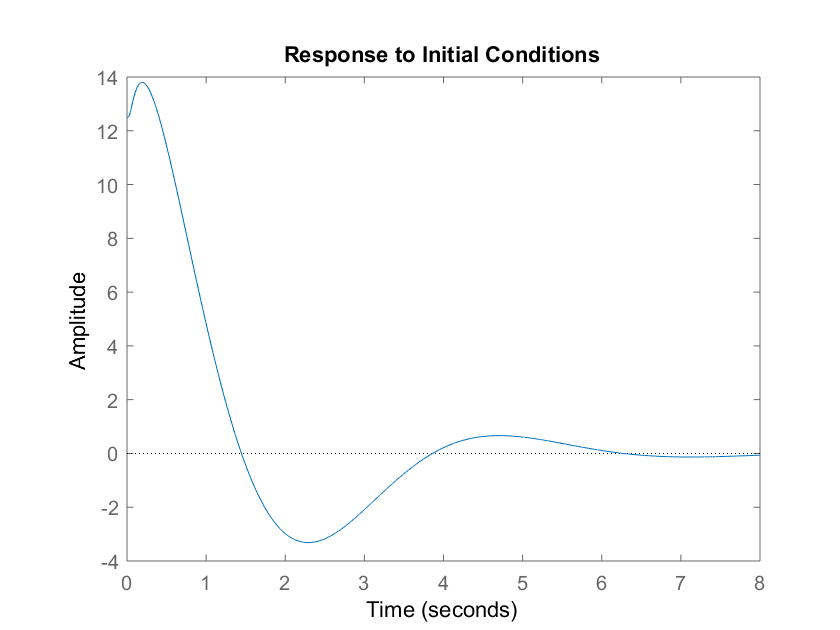

regulator = reg(Gss,K,L);
T = feedback(Gss*regulator,-1);  %Regulators demand positive feedback
initial(T,[0;0;1;zeros(3,1)])

**Problem 3**

Load the model and see what I'm up against

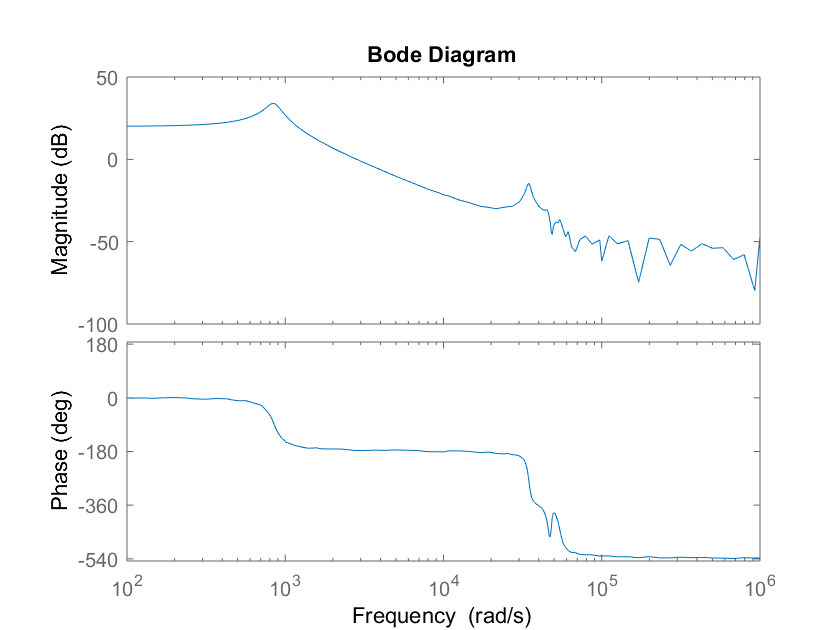

load HDD_freqresp;
P = HDD_freqresp;
bode(P);

Problem 3a

I'll use some classical loop shaping to get the desired results.

Pd = P*exp(-1/50000/2*s);  %Model with time delay
wc = 1000*2*pi;  %Set the crossover frequency - can get any value we want!

I'll start with the integral action.  A good rule of thumb is to place the zero of a PI compensator at 1/10 of the crossover frequency.

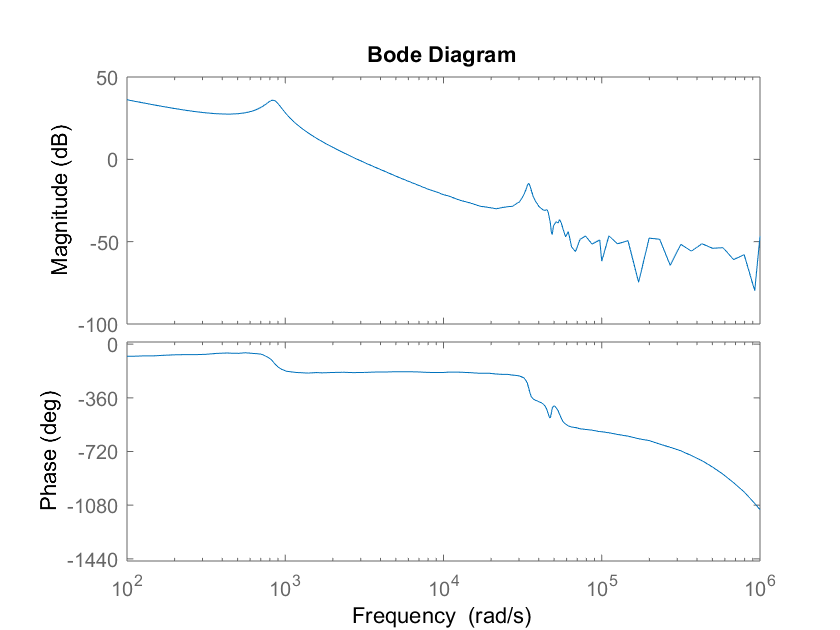

Cpi = (s+wc/10)/s;
bode(Pd*Cpi)

Now I want to see if I can get away with just a lead compensator.

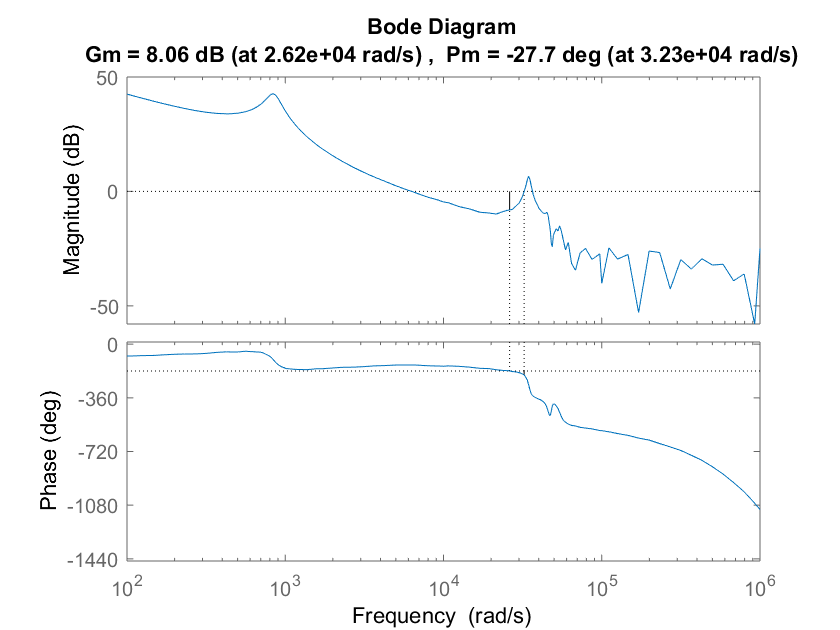

PM = 40;
[mag,phase] = bode(Pd*Cpi,wc);
lead_angle = (-180-phase)+PM;
Clead = lead(lead_angle,wc);
[mag,phase] = bode(Pd*Cpi*Clead,wc);
K = 1/mag;
margin(Pd*Cpi*Clead*K)

Unfortunately, it looks like I need to notch the resonant mode.  After playing around a little I settled on

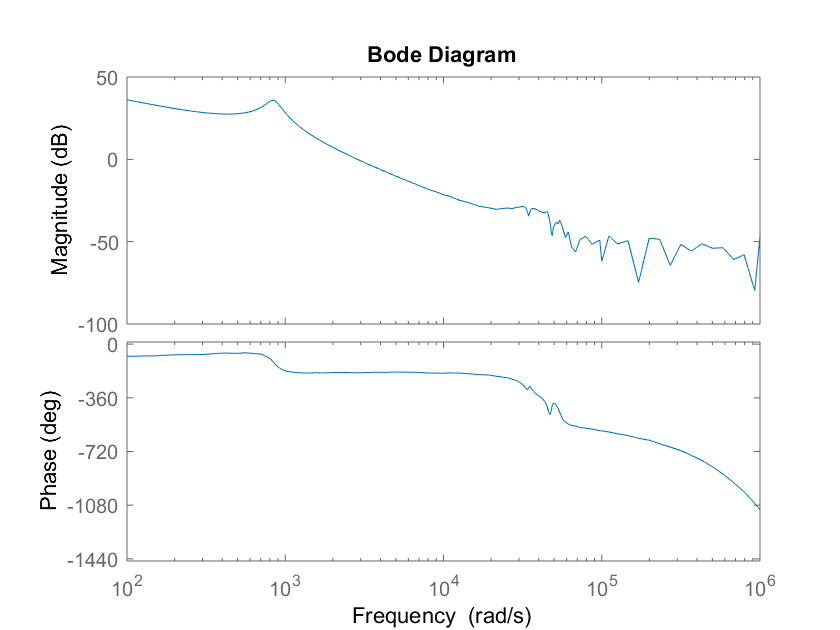

N1 = notch(20,1000,34500);
bode(Pd*N1*Cpi)

Now try again with the notch.

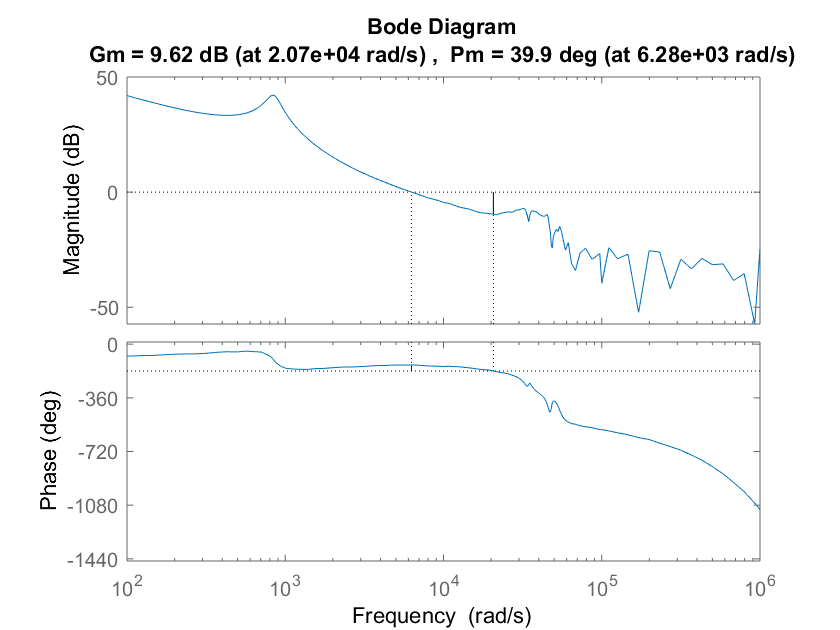

[mag,phase] = bode(Pd*Cpi*N1,wc);
lead_angle = (-180-phase)+PM;
Clead = lead(lead_angle,wc);
[mag,phase] = bode(Pd*Cpi*Clead*N1,wc);
k = 1/mag;
margin(Pd*Cpi*Clead*k*N1)

Success!

K = Cpi*Clead*k*N1;

Part 3b

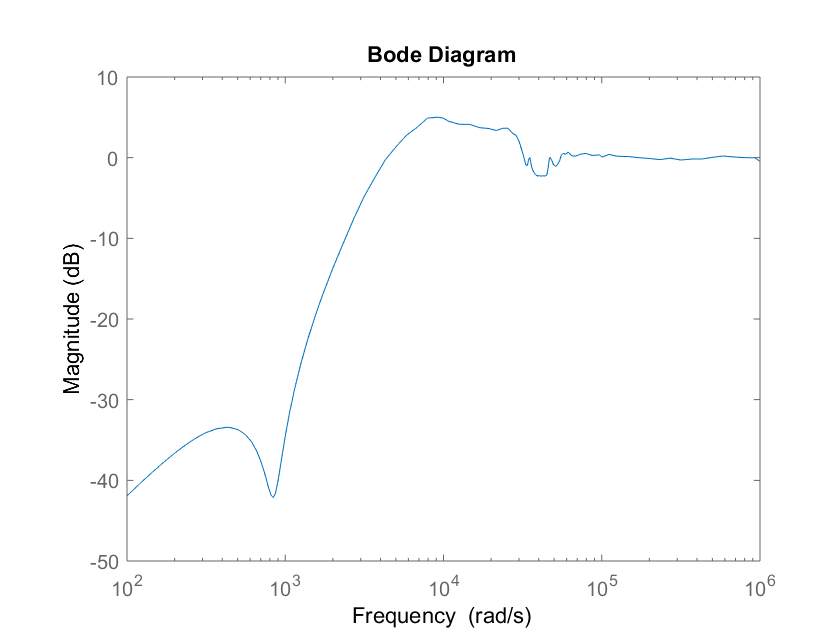

S = 1/(1+Pd*K);
T = 1-S;
bodemag(S)

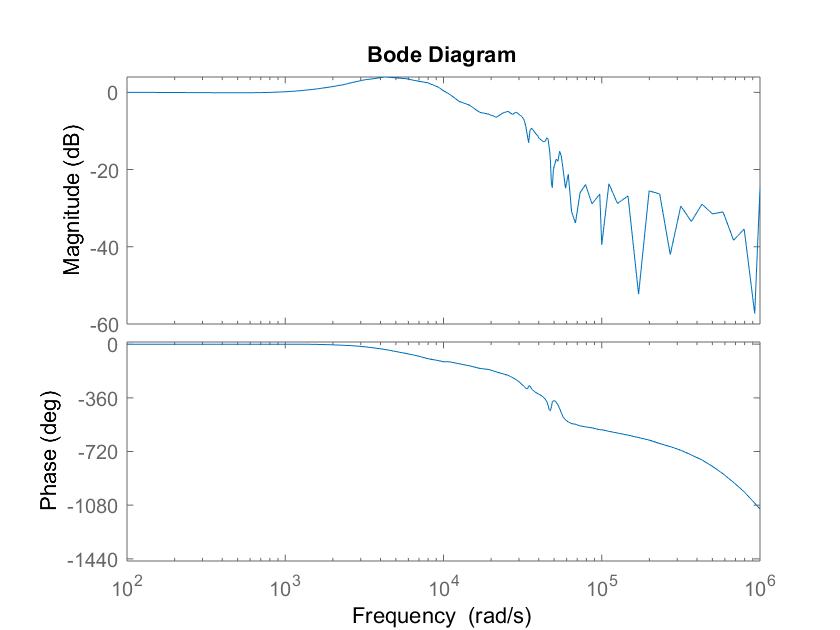

bode(T)

Now let's find the peaks.

[mag,phase] = bode(S);
mag = mag(:);
Smax = max(mag)

Smax = 1.7822

[mag,phase] = bode(T);
Tmax = max(mag)

Tmax = 1.5793

These two are very close, as usual.

Part 3c

Fitfrd is a relatively easy function to use, but we still probably need to be careful to fit a good model.  Just looking at it, maybe a 4th order model would be appropriate, and I think the relative degree approximately 1.

Tapprox = fitfrd(T,4,1,[]);

It is not uncommon, especially for systems with time delays, for fitfrd to return nonminimum phase systems.  To get the bode plots to look nice, I sometimes force the phase to be near 0 degrees at the start.

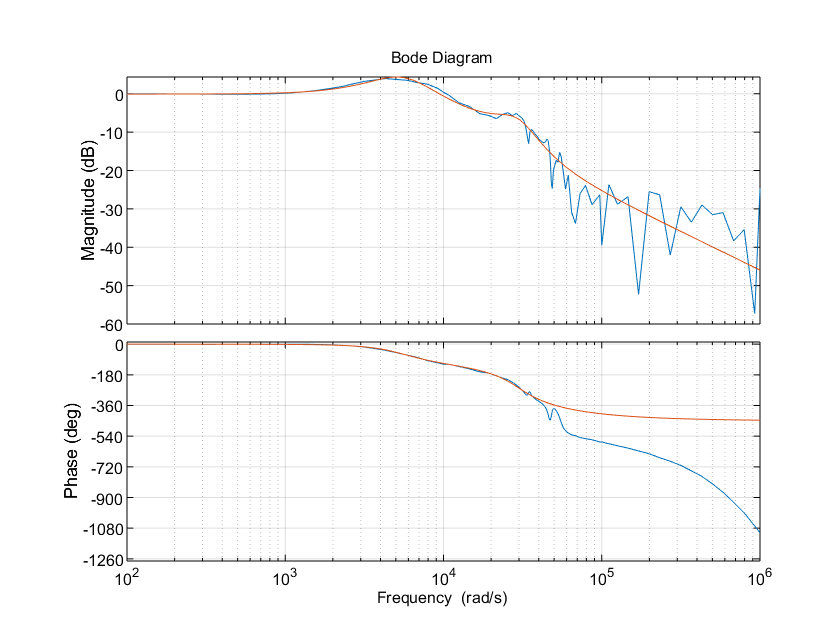

opt = bodeoptions;
opt.grid = 'on';
opt.Phasematching = 'on';
opt.PhaseMatchingFreq = 0;
opt.PhaseMatchingValue = 0;
bodeplot(T,Tapprox,opt)

Now look at the approximate step response.

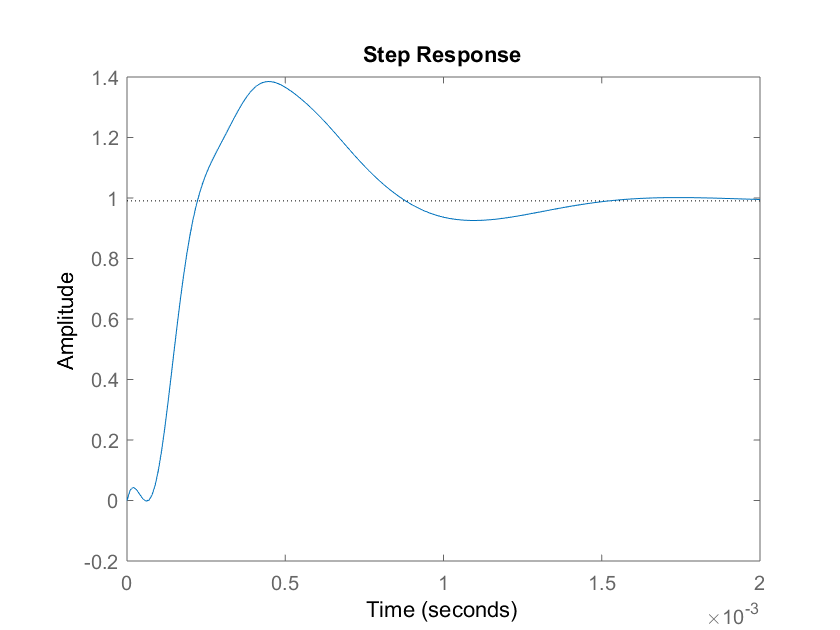

step(Tapprox);